% Demo_Dynamics_NE_2Link
% 1. 手动推到的NE动力学方程
% 2. 用DH方法+NE程序推导的动力学方程


如图所示，已知两连杆机器人的结构和惯性参数，采用NewtonEular方法推导其动力学方程，最终获得H，C，G三个矩阵。

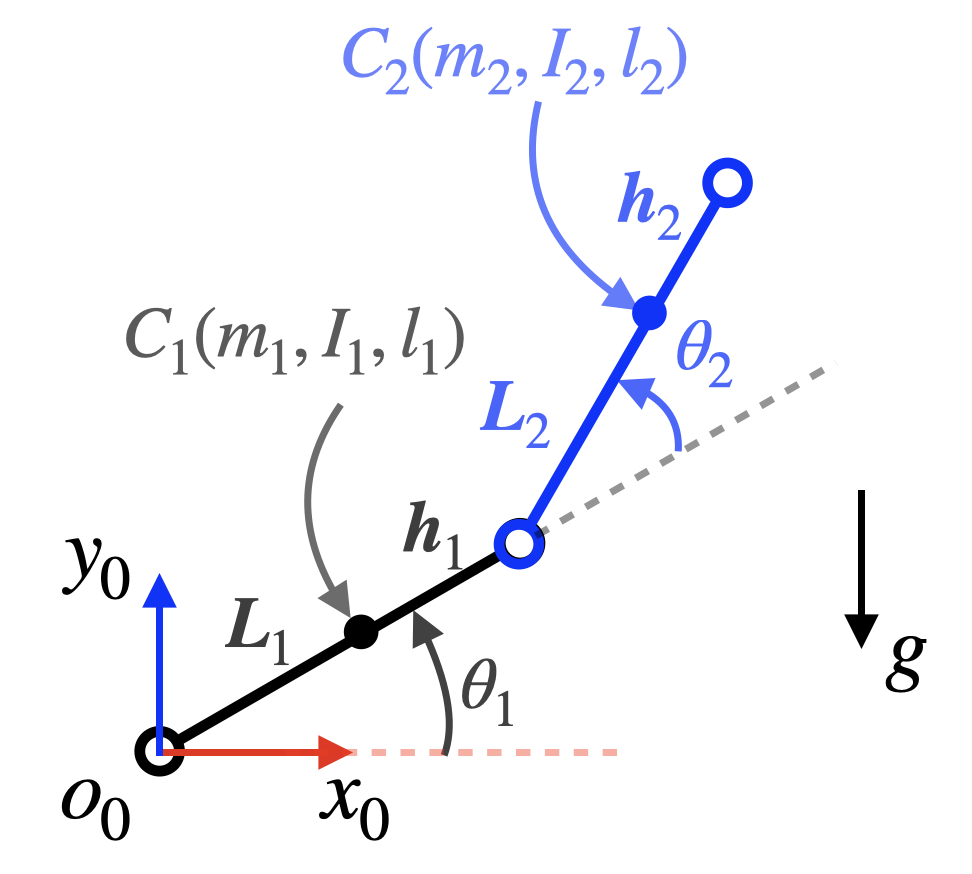，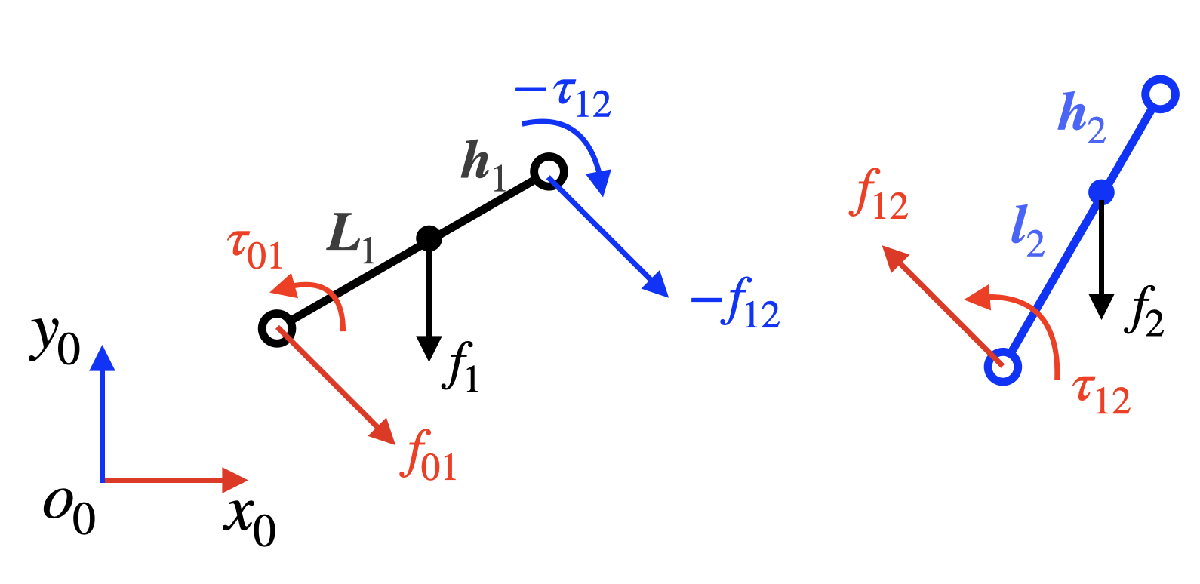

% 用Newton-Eular方法手动推导2连杆机器人的动力学方程

clc
clear
close all

% 定义表示机器人动力学的符号变量
syms m1 m2 
syms Ic1 Ic2
syms L1 L2 
syms d1 d2 
syms g       
syms theta1 omega1 epsilon1 
syms omega2 epsilon2
syms F tau

IC1 = [0 0 0; 0 0 0; 0 0 Ic1];
IC2 = [0 0 0; 0 0 0; 0 0 Ic2];

% 动力学推导
% 1. 运动学外推(连杆1～2)
% 1.1 连杆1
theta01 = [0; 0; theta1];
XC01 = rotz(theta01(3)) * [d1; 0; 0];

VC01    = jacobian(XC01,theta1)*omega1 + jacobian(XC01,d2)*omega2;
omega01 = jacobian(theta01,theta1)*omega1 + jacobian(theta01,d2)*omega2;

AC01 = jacobian(VC01,theta1)*omega1 + jacobian(VC01,d2)*omega2 ...
     + jacobian(VC01,omega1)*epsilon1 + jacobian(VC01,omega2)*epsilon2;

epsilon01 = jacobian(omega01,theta1)*omega1 + jacobian(omega01,d2)*omega2 ...
          + jacobian(omega01,omega1)*epsilon1 + jacobian(omega01,omega2)*epsilon2;


% 1.2 连杆2
theta02 = theta01; 
XC02 = rotz(theta01(3)) * [d2; 0; 0];
VC02    = jacobian(XC02,theta1)*omega1 + jacobian(XC02,d2)*omega2;
omega02 = jacobian(theta02,theta1)*omega1 + jacobian(theta02,d2)*omega2;

AC02 = jacobian(VC02,theta1)*omega1 + jacobian(VC02,d2)*omega2 ...
     + jacobian(VC02,omega1)*epsilon1 + jacobian(VC02,omega2)*epsilon2;

epsilon02 = jacobian(omega02,theta1)*omega1 + jacobian(omega02,d2)*omega2 ...
          + jacobian(omega02,omega1)*epsilon1 + jacobian(omega02,omega2)*epsilon2;


% 2. 动力学内推（连杆2～1）
% 2.1 连杆2
f2 = m2*[0; -g; 0];
F2 = [F*cos(theta1);F*sin(theta1);0];
f12 = m2*AC02 - f2 - F2;

% LC2 = rotz(theta02(3)) * [-(d2-d1); 0; 0];
% tau12 = IC2*epsilon02 - cross(LC2, f12);
% tau12 = [0, 0, 0];
% 最后一个连杆，没有其他力矩存在

% 2.2 连杆1
f1 = m1*[0; -g; 0];
f01 = m1*AC01 + f12 - f1;   

LC1 = -XC01;
H1 = [d2-d1; 0; 0];
tau01 = [0;0;tau];
tau12 = -IC1*epsilon01 + cross(LC1, f01) + tau01 - cross(H1, f12);


% 3 获得动力学方程
% 3.1 关节力矩的表达式
tau = simplify([tau01(3); tau12(3)]);

% 3.2 计算HCQ矩阵
q = [theta1; d2];
q_d = [omega1; omega2];
q_dd = [epsilon1; epsilon2];

H = simplify(jacobian(tau,q_dd))

$$H = \left(\begin{array}{cc} 0 & 0\\ d_{1}\,d_{2}\,m_{2}\,\cos\left(\theta_{1}\right)-{d_{1}}^{2}\,m_{1}-{d_{2}}^{2}\,m_{2}\,\cos\left(\theta_{1}\right)-d_{1}\,d_{2}\,m_{2}-{\mathrm{Ic}}_{1} & m_{2}\,\sin\left(\theta_{1}\right)\,\left(d_{1}-d_{2}\right) \end{array}\right)$$

C = simplify(jacobian(tau,q_d))

$$C = \left(\begin{array}{cc} 0 & 0\\ -2\,m_{2}\,\left(d_{1}\,\omega_{2}-d_{1}\,\omega_{2}\,\cos\left(\theta_{1}\right)+d_{2}\,\omega_{2}\,\cos\left(\theta_{1}\right)-{d_{2}}^{2}\,\omega_{1}\,\sin\left(\theta_{1}\right)+d_{1}\,d_{2}\,\omega_{1}\,\sin\left(\theta_{1}\right)\right) & -2\,m_{2}\,\omega_{1}\,\left(d_{1}-d_{1}\,\cos\left(\theta_{1}\right)+d_{2}\,\cos\left(\theta_{1}\right)\right) \end{array}\right)$$

G = simplify(jacobian(tau,g)*g)

$$G = \left(\begin{array}{c} 0\\ -g\,\left(d_{2}\,m_{2}-d_{1}\,m_{2}+d_{1}\,m_{1}\,\cos\left(\theta_{1}\right)+d_{1}\,m_{2}\,\cos\left(\theta_{1}\right)\right) \end{array}\right)$$


% 4 对比参考资料上的结果
% tau = subs(tau, {Ic1 Ic2 d1 Lc2},{0 0 L1 L2}); 
% H = simplify(jacobian(tau,q_dd))
% C = simplify(jacobian(tau,q_d))
% G = simplify(jacobian(tau,g)*g)

% 编写Newton-Eular+MDH构成的动力学推导程序，带入两连杆机器人的参数后，用程序求解，
clc
clear 
close all

syms q1 q2 m1 m2 L1 L2 Lc1 Lc2 Ix1 Iy1 Iz1 Ix2 Iy2 Iz2 dq1 dq2 ddq1 ddq2 g

% MDH parameters
%            alpha a   d  theta
dh_params = [ 0,   0,  0, q1; 
              0,   L1, 0, q2;  
              0,   L2, 0, 0 ];
         
%               x   y   z
mass_center = [Lc1, 0,  0;  
               Lc2, 0,  0;  ];

%
mass = [m1,m2];

% 只有主惯性 
inertia_1 = [Ix1, 0,    0;
             0,   Iy1,  0;
             0,   0,    Iz1];
         
inertia_2 = [Ix2,   0,      0;
             0,     Iy2,    0; 
             0,     0,      Iz2];

% 构成惯性张量
inertia_tensor(:,:,1) = inertia_1;
inertia_tensor(:,:,2) = inertia_2;

% external force，no contact force
%        x   y   z
f_ext = [0,  0,  0;     
         0,  0,  0];     

% 
torque =  NewtonEulerDynamics(dh_params, mass, mass_center, inertia_tensor, f_ext);
torque = simplify(torque)

$$torque = \left(\begin{array}{c} {\mathrm{Iz}}_{1}\,{\mathrm{ddq}}_{1}+{\mathrm{Iz}}_{2}\,{\mathrm{ddq}}_{1}+{\mathrm{Iz}}_{2}\,{\mathrm{ddq}}_{2}+{L_{1}}^{2}\,{\mathrm{ddq}}_{1}\,m_{2}-{{\mathrm{Lc}}_{1}}^{2}\,{\mathrm{ddq}}_{1}\,m_{1}-{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{ddq}}_{1}\,m_{2}-{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{ddq}}_{2}\,m_{2}+{\mathrm{Lc}}_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)-L_{1}\,g\,m_{2}\,\cos\left(q_{1}\right)+{\mathrm{Lc}}_{1}\,g\,m_{1}\,\cos\left(q_{1}\right)-2\,L_{1}\,{\mathrm{Lc}}_{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{2}\,\sin\left(q_{2}\right)-L_{1}\,{\mathrm{Lc}}_{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,\sin\left(q_{2}\right)+L_{1}\,{\mathrm{Lc}}_{2}\,{\mathrm{ddq}}_{2}\,m_{2}\,\cos\left(q_{2}\right)-2\,L_{1}\,{\mathrm{Lc}}_{2}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{Iz}}_{2}\,\left({\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2}\right)-{\mathrm{Lc}}_{2}\,m_{2}\,\left(\cos\left(q_{2}\right)\,\left(L_{1}\,{\mathrm{ddq}}_{1}-g\,\cos\left(q_{1}\right)\right)+\sin\left(q_{2}\right)\,\left(L_{1}\,{{\mathrm{dq}}_{1}}^{2}+g\,\sin\left(q_{1}\right)\right)+{\mathrm{Lc}}_{2}\,\left({\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2}\right)\right) \end{array}\right)$$

q = [q1; q2];
q_d = [dq1; dq2];
q_dd = [ddq1; ddq2];

H = simplify(jacobian(torque,q_dd))

$$H = \left(\begin{array}{cc} m_{2}\,{L_{1}}^{2}-m_{1}\,{{\mathrm{Lc}}_{1}}^{2}-m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+{\mathrm{Iz}}_{1}+{\mathrm{Iz}}_{2} & -m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{Lc}}_{2}+{\mathrm{Iz}}_{2}\\ {\mathrm{Iz}}_{2}-{\mathrm{Lc}}_{2}\,m_{2}\,\left({\mathrm{Lc}}_{2}+L_{1}\,\cos\left(q_{2}\right)\right) & {\mathrm{Iz}}_{2}-{{\mathrm{Lc}}_{2}}^{2}\,m_{2} \end{array}\right)$$

C = simplify(jacobian(torque,q_d))

$$C = \left(\begin{array}{cc} -2\,L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right) & -2\,L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\\ -2\,L_{1}\,{\mathrm{Lc}}_{2}\,{\mathrm{dq}}_{1}\,m_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

G = simplify(jacobian(torque,g)*g)

$$G = \left(\begin{array}{c} g\,\left({\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)-L_{1}\,m_{2}\,\cos\left(q_{1}\right)+{\mathrm{Lc}}_{1}\,m_{1}\,\cos\left(q_{1}\right)\right)\\ {\mathrm{Lc}}_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

采用RTB系统工具箱中的方法（RNE）

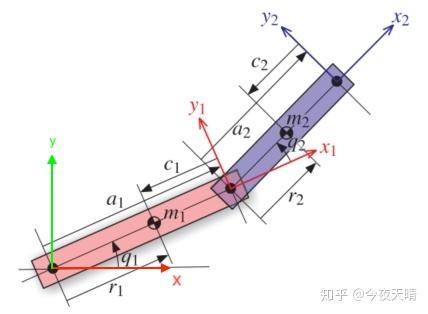

clc
clear
close all

% 定义符号变量
syms m1 m2 Ic1 Ic2 g
syms L1 L2 Lc1 Lc2 
syms q1 q2 q1_d q2_d q1_dd q2_dd

twolink = SerialLink([
    Revolute('d', 0, 'a', L1, 'alpha', 0, 'm', m1,  'I', [0 0 Ic1], 'standard')
    Revolute('d', 0, 'a', L2, 'alpha', 0, 'm', m2,  'I', [0 0 Ic2], 'standard')
    ], ...
    'name', 'two link');

twolink = twolink.sym()         % 显示该机器人的DH参数，及主要信息（slowRNE，Symbolic）

 
twolink = 
 
two link:: 2 axis, RR, stdDH, slowRNE, Symbolic                  
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         L1|          0|          0|
|  2|         q2|          0|         L2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


twolink.base                    % 最初基座是和世界坐标系（绝对）重合的

 

ans = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


twolink.gravity                 % 重力[0; 0; 9.81]，但实际是z轴的负方向。可能是rne的默认。但我们一般写成矢量为：[0;0;-9.81]

ans =          0
         0
    9.8100


twolink.gravity = [0; 0; g];    % 更改9.803为符号g
twolink.base = trotx(pi/2);     % 改变基坐标系的方向，使y轴在纸面上是竖直向上的，这时Z0是指向纸面的，前面的DH参数才合理。


tau = twolink.rne([q1 q2], [q1_d q2_d], [q1_dd q2_dd]);
tau = simplify([tau(1);tau(2)])     % 不要用转置，会影响符号的显示。

$$tau = \left(\begin{array}{c} {\mathrm{Ic}}_{1}\,q_{1,\mathrm{dd}}+{\mathrm{Ic}}_{2}\,q_{1,\mathrm{dd}}+{\mathrm{Ic}}_{2}\,q_{2,\mathrm{dd}}+{L_{1}}^{2}\,m_{1}\,q_{1,\mathrm{dd}}+{L_{1}}^{2}\,m_{2}\,q_{1,\mathrm{dd}}+{L_{2}}^{2}\,m_{2}\,q_{1,\mathrm{dd}}+{L_{2}}^{2}\,m_{2}\,q_{2,\mathrm{dd}}+L_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,g\,m_{1}\,\cos\left(q_{1}\right)+L_{1}\,g\,m_{2}\,\cos\left(q_{1}\right)-L_{1}\,L_{2}\,m_{2}\,{q_{2,d}}^{2}\,\sin\left(q_{2}\right)+2\,L_{1}\,L_{2}\,m_{2}\,q_{1,\mathrm{dd}}\,\cos\left(q_{2}\right)+L_{1}\,L_{2}\,m_{2}\,q_{2,\mathrm{dd}}\,\cos\left(q_{2}\right)-2\,L_{1}\,L_{2}\,m_{2}\,q_{1,d}\,q_{2,d}\,\sin\left(q_{2}\right)\\ {\mathrm{Ic}}_{2}\,\left(q_{1,\mathrm{dd}}+q_{2,\mathrm{dd}}\right)+L_{2}\,m_{2}\,\left(\cos\left(q_{2}\right)\,\left(L_{1}\,q_{1,\mathrm{dd}}+g\,\cos\left(q_{1}\right)\right)+\sin\left(q_{2}\right)\,\left(L_{1}\,{q_{1,d}}^{2}-g\,\sin\left(q_{1}\right)\right)+L_{2}\,\left(q_{1,\mathrm{dd}}+q_{2,\mathrm{dd}}\right)\right) \end{array}\right)$$


% 获得HCG
q = [q1; q2];
q_d = [q1_d; q2_d];
q_dd = [q1_dd; q2_dd];

H = simplify(jacobian(tau,q_dd))    

$$H = \left(\begin{array}{cc} {\mathrm{Ic}}_{1}+{\mathrm{Ic}}_{2}+{L_{1}}^{2}\,m_{1}+{L_{1}}^{2}\,m_{2}+{L_{2}}^{2}\,m_{2}+2\,L_{1}\,L_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{L_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\right)\,L_{2}+{\mathrm{Ic}}_{2}\\ {\mathrm{Ic}}_{2}+L_{2}\,m_{2}\,\left(L_{2}+L_{1}\,\cos\left(q_{2}\right)\right) & m_{2}\,{L_{2}}^{2}+{\mathrm{Ic}}_{2} \end{array}\right)$$

C = simplify(jacobian(tau,q_d))

$$C = \left(\begin{array}{cc} -2\,L_{1}\,L_{2}\,m_{2}\,q_{2,d}\,\sin\left(q_{2}\right) & -2\,L_{1}\,L_{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left(q_{1,d}+q_{2,d}\right)\\ 2\,L_{1}\,L_{2}\,m_{2}\,q_{1,d}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

G = simplify(jacobian(tau,g)*g)

$$G = \left(\begin{array}{c} g\,\left(L_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,m_{1}\,\cos\left(q_{1}\right)+L_{1}\,m_{2}\,\cos\left(q_{1}\right)\right)\\ L_{2}\,g\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

function torque_list = NewtonEulerDynamics(dh_list, mass_list, mass_center_list, inertia_tensor_list, f_external)
% 这个函数需要更改，有个地方的符号可能有问题

% 输入参数：
% dh_list：机器人MDH参数
% mass_list: 连杆的质量，单位kg
% mass_center_list：连杆质心在连杆坐标系下的位置，单位：m
% inertia_tensor_list：连杆关于质心坐标系的惯性张量，质心坐标系与连杆坐标系方位一致
% f_external：施加在末端连杆的外力和外力矩

% 输出参数：
% torque_list：用q,dq,ddq（关节位置、速度、加速度）表达的关节力矩
% 重力加速度符号
syms g real

[rows, columns] = size(dh_list);
number_of_links = rows - 1;
if columns ~= 4
    error('wrong DH parameters!')
end

T = sym([]);
R = sym([]);
a = sym([]);
d = sym([]);
alpha = sym([]);
theta = sym([]);

% 定义关节位置，速度，加速度符号
for i = 1:rows
    eval(['syms ','q',      num2str(i),';'])
    eval(['syms ','dq',     num2str(i),';'])
    eval(['syms ','ddq',    num2str(i),';'])
    eval(['q(i)=','q',      num2str(i),';'])
    eval(['dq(i)=','dq',    num2str(i),';'])
    eval(['ddq(i)=','ddq',  num2str(i),';'])
end

for i = 1:rows
    dh = dh_list(i,:);

    % MDH
    alpha(i) = dh(1);       
    a(i) = dh(2);
    d(i) = dh(3);           
    theta(i) = dh(4);

    % q
    if i == rows
        q(i) = 0;
    end
    
    % T matrix with MDH paparmeters
    T(:,:,i) = [cos(q(i)),               -sin(q(i)),              0,                   a(i);
                sin(q(i))*cos(alpha(i)), cos(q(i))*cos(alpha(i)), -sin(alpha(i)),      -sin(alpha(i))*d(i);
                sin(q(i))*sin(alpha(i)), cos(q(i))*sin(alpha(i)), cos(alpha(i)),       cos(alpha(i))*d(i);
                0,                       0,                       0,                   1];
    T = T(:,:,i);

    % 提取旋转矩阵R并求逆
    R(:,:,i) = simplify(inv(T(1:3,1:3)));

    % 提取坐标系原点位置P
    P(:,:,i) = T(1:3,4:4);
end

% MDH规定关节轴都是z轴方向
z = [0,0,1]';

% +++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Newtow-Eular方法
% 外推 --->
for i = 0:number_of_links-1
    % 前一个连杆的角速度、角加速度，加速度
    if i == 0
        wi =  [0, 0, 0]';
        dwi = [0, 0, 0]';
        dvi = [0, -g, 0]';  %沿-y，g=9.8
    else
        wi = w(:,i);
        dwi = dw(:,i);
        dvi = dv(:,i);
    end
    
    % 当前连杆的
    % 角速度、角加速度
    w(:,:,i+1)  = R(:,:,i+1)*wi + dq(i+1)*z;
    dw(:,:,i+1) = R(:,:,i+1)*dwi + cross(R(:,:,i+1)*wi,dq(i+1)*z) + ddq(i+1)*z;

    % 速度、加速度
    dv(:,:,i+1) = R(:,:,i+1)*(cross(dwi,P(:,:,i+1)) + cross(wi,cross(wi, P(:,:,i+1))) + dvi);
    dvc(:,:,i+1) = cross(dw(:,:,i+1), transpose(mass_center_list(i+1,:)))...
                    + cross(w(:,:,i+1), cross(w(:,:,i+1), transpose(mass_center_list(i+1,:))))...
                    + dv(:,:,i+1);
    
    % 牛顿-欧拉公式，并存储到F，N中
    F(:,:,i+1) = mass_list(i+1)*dvc(:,:,i+1);
    N(:,:,i+1) = inertia_tensor_list(:,:,i+1)*dw(:,:,i+1) ...
                 + cross(w(:,:,i+1),inertia_tensor_list(:,:,i+1)*w(:,:,i+1));
end

% 
f = sym([]);
n = sym([]);


% 内推 <---
for i = number_of_links:-1:1
    % 最后一个连杆的受力
    if i == number_of_links
        f(:,:,i+1) = f_external(1,:)';
        n(:,:,i+1) = f_external(2,:)';
    end

    % 连杆受到的力
    f(:,:,i) = inv(R(:,:,i+1))*f(:,:,i+1) + F(:,:,i);
    f(:,:,i) = simplify(f(:,:,i));
    
    % 连杆受到的力矩
    n(:,:,i) = N(:,:,i) ...
                + R(:,:,i+1)\n(:,:,i+1) ...
                - cross(transpose(mass_center_list(i,:)), F(:,:,i))...
                + cross(P(:,:,i+1),R(:,:,i+1)\f(:,:,i+1));
    n(:,:,i) = simplify(n(:,:,i));
    
    % 投影到z轴
    torque_list(i) = dot(n(:,:,i),z);
end

torque_list = torque_list';

% end of this function
end